# Ordinary Differential Equations

## Introduction

### Definition of a Differential Equation			

A *differential equation is *an equation involving derivatives or differentials. The following are some examples of differential equations.

        **Example 1.** $(y\prime\prime)^2+3x=2(y\prime)^3$ where $y\prime=\frac{\mathrm dy}{\mathrm dx}$, $y\prime\prime=\frac{\mathrm d^2y}{\mathrm dx^2}$

        **Example 2.** $\frac{\mathrm dy}{\mathrm dx}+\frac{y}{x}=y^2$

        **Example 3.** $\frac{\mathrm d^2Q}{\mathrm dt^2}-3\frac{\mathrm dQ}{\mathrm dt}+2Q=4\sin2t$ or $\ddot Q-3\dot Q+2Q=4\sin2t$

        **Example 4. **$\frac{\mathrm dy}{\mathrm dx}=\frac{x+y}{x-y}$ or $(x+y)\mathrm dx+(y-x)\mathrm dy=0$

        **Example 5.** $\frac{\partial^2V}{\partial x^2}+\frac{\partial^2V}{\partial y^2}=0$

Equations such as those in Examples 1-4 involving only one independent variable are called *ordinary differential equations. *Equations such as that of Example 5 with two or more independent variables are called *partial differential equations *and are treated in Lecture 03.

### Order of a Differential Equation

An equation having a derivative of $n$th order but no higher is called an $n$th *order differential equation. *In Examples 1-5 above, the orders of the differential equations are 2,1, 2,1, 2, respectively.

### Arbitrary Constants

An arbitrary constant, often denoted by a letter at the beginning of the alphabet such as $A$*, *$B$*, *$C$*, *$c_1$, $c_2$, etc., may assume values independently of the variables involved. For example in $y= x^2+c_1 x+c_2$, $c_1$ and $c_2$ are arbitrary constants. 

The relation $y = A\mathrm e^{-4x +B}$ which can be written $y = A\mathrm e^B\mathrm e^{-4x}=C\mathrm e^{-4x}$ actually involves only one arbitrary constant. We shall always assume that the minimum number of constants is present, i.e. the arbitrary constants are *essential. *

### Solution of Differential Equation

A *solution *of a differential equation is a relation between the variables which is free of derivatives and which satisfies the differential equation identically.

        **Example 6.** $y=x^2+c_1x+c_2$ is a solution of $y\prime\prime =2$ since by substitution we obtain the identity $2=2$.

A *general solution* of an $n$th order differential equation is one involving $n$ (essential) arbitrary constants.

        **Example 7.** Since $y=x^2+c_1x+c_2$ has two arbitrary constants and satifies the second order differential equation $y\prime\prime =2\,,$ it is a general solution of $y\prime\prime =2$.  

*A particular solution *is a solution obtained from the general solution by assigning specific values to the arbitrary constants. 

        **Example 8.** Since $y=x^2-3x+2$ is a particular solution of $y\prime\prime =2$, and is obtained from the general solution $y=x^2+c_1x+c_2$ by putting $c_1=-3$ and $c_2=2$.

A *singular solution *is a solution which cannot be obtained from the general solution by specifying values of the arbitrary constants. 					

        **Example 9.** The general solution of $y=xy\prime-y\prime^2$ is $y=cx-c^2$*. *However, as seen by substitution another solution is $y=\frac{x^2}{4}$ which cannot be obtained from the general solution for any constant $c$. This second solution is a singular solution.

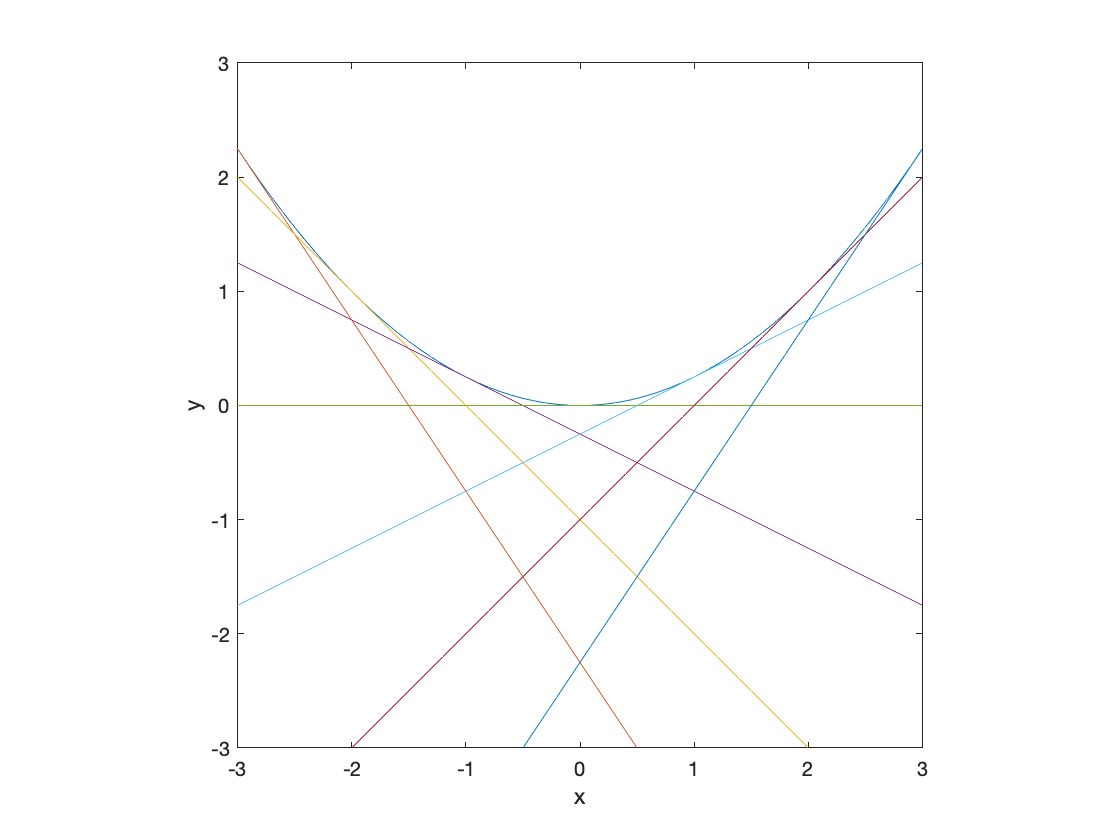

figure
x = -3:0.1:3;
y = x.^2/4;
plot(x,y); xlabel('x'); ylabel('y')
hold on
for c = -1.5:0.5:1.5
    plot(x, c*x-c^2)
end
axis equal
axis([-3 3 -3 3])

It is seen that $y=cx-c^2$ represents a family of straight lines tangent to the parabola $y=\frac{x^2}{4}$*. *The parabola is the *envelope *of the family of straight lines.

The envelope of a family of curves $G(x, y, c)=0$, if it exists, can be found by solving simultaneously the equations $\frac{\partial G}{\partial c} = 0$ and $G=0$. In this example $G(x,y, c) = y-cx+c^2$ and $\frac{\partial G}{\partial c} = -x+2c$. Solving simultaneously $-x+2c=0$ and $y-cx+c^2=0$, we find $x=2c$*, *$y=c^2$ or $y=\frac{x^2}{4}$*. *